# PDCCH资源映射

在5G通信系统中，PDCCH（Physical Downlink Control Channel）是下行物理控制信道，用于传输控制信息。PDCCH的资源映射是确定PDCCH占用资源的过程。

PDCCH的资源映射基于用于物理资源分配的REG（Resource-Element Group）和CCE（Control Channel Element）的概念。

PDCCH资源映射步骤如下：

1、载波和PDCCH资源配置。通过CORESET和Searchspace配置PDCCH资源。

2、根据CORESET配置计算PRB、REG、REG bundle、CCE的映射关系。（根据38.211）

3、根据Searchspace分配聚合度和候选集配置计算分配的CCE。（根据38.213）

4、在分配的CCE上映射PDCCH symbol和DMRS。

## 1、载波和PDCCH资源配置

clear;
clc;
close all;

% Carrier configuration
carrier = nrCarrierConfig;
carrier.NCellID = 2;                    % Cell identity
carrier.SubcarrierSpacing = 30;         % Carrier/BWP Subcarrier spacing
carrier.CyclicPrefix = 'normal';        % Cyclic prefix
carrier.NSlot      = 0;                 % Slot counter
carrier.NFrame     = 0;                 % Frame counter
carrier.NStartGrid = 0;                 % Carrier offset
carrier.NSizeGrid  = 51;               % Size of carrier in RB

% CORESET configuration
coreset = nrCORESETConfig;
coreset.CORESETID = 1;                  % CORESET ID (0...11)
coreset.FrequencyResources = ones(1,8); % 6 RB sized
coreset.Duration = 1;                   % CORESET symbol duration (1,2,3)
coreset.CCEREGMapping = 'noninterleaved';  % CORESET Mapping (interleaved, noninterleaved)
coreset.REGBundleSize = 2;              % L (2,6) or (3,6)
coreset.InterleaverSize = 3;            % R (2,3,6)
coreset.ShiftIndex = 3;   % default to NCellID

% Search space configuration
ss = nrSearchSpaceConfig;
ss.CORESETID = 1;                       % Associated CORESET ID (0...11)
ss.SearchSpaceType = 'ue';              % 'ue', 'common'
ss.StartSymbolWithinSlot = 0;           % Starting symbol in slot
ss.SlotPeriodAndOffset = [1 0];         % Search space period and offset
ss.Duration = 1;                        % Search space duration in slots
ss.NumCandidates = [4 4 4 0 0];         % For (1,2,4,8,16) levels respectively

% PDCCH configuration
pdcch = nrPDCCHConfig;
pdcch.NStartBWP  = carrier.NStartGrid;  % BWP offset wrt CRB 0
pdcch.NSizeBWP   = carrier.NSizeGrid;   % Size of BWP in resource blocks
pdcch.CORESET = coreset;                % Associated CORESET
pdcch.SearchSpace = ss;                 % Associated SearchSpace
pdcch.RNTI = 1;                         % C-RNTI
pdcch.DMRSScramblingID = carrier.NCellID + pdcch.RNTI;
pdcch.AggregationLevel = 2;             % Number of CCEs in PDCCH (1,2,4,8,16)
pdcch.AllocatedCandidate = 3;           % 1-based scalar

## 2、CORESET资源映射

CORESET由频域中的N_CORESET_RB个RB和时域中的duration个符号组成。CCE由6个REG组成，其中一个REG等于一个OFDM符号期间的一个RB。CORESET中的REG，从第一个OFDM符号和控制资源集中的最小编号RB开始，按时域优先的方式以递增顺序编号，起始编号为0。

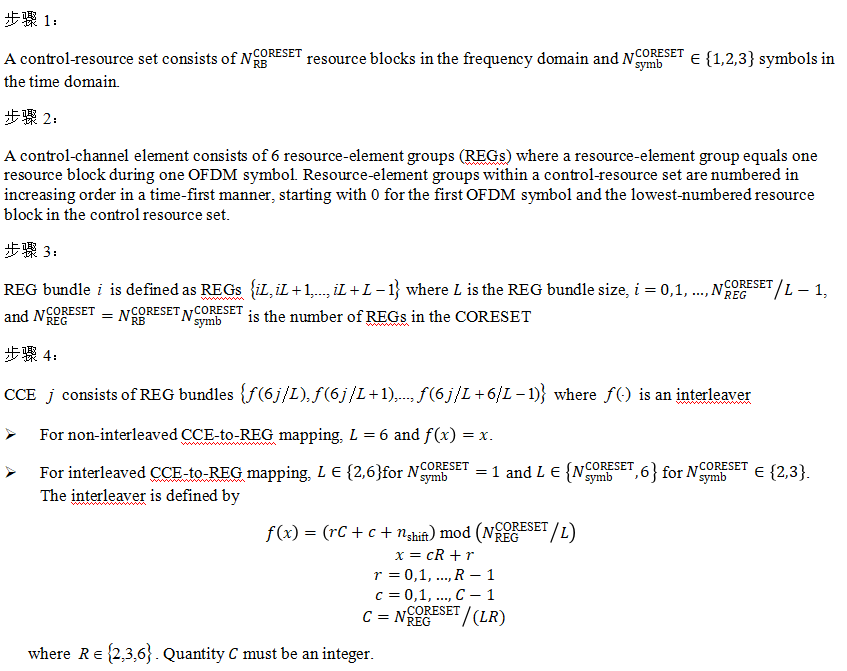

步骤4也可通过交织器实现，原理如下：

交织表如下所示，表的行数为R，标的列数为C。表的编排形式是**行进列出**：

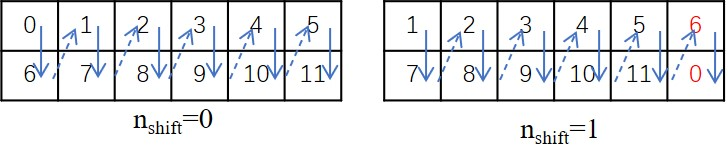

当nshift = 0 时，读取REG-bundle的编号为：0 6 1 7 2 8 3 9 4 10 5 11；

当nshift = 1 时，读取REG-bundle的编号为：1 7 2 8 3 9 4 10 5 11 6 0。

resource_map = getCoresetResourceMap(pdcch);
disp(resource_map);

    prb_map    reg_map    reg_bundle_map    cce_map
    _______    _______    ______________    _______

      47         47             7              7   
      46         46             7              7   
      45         45             7              7   
      44         44             7              7   
      43         43             7              7   
      42         42             7              7   
      41         41             6              6   
      40         40             6              6   
      39         39             6              6   
      38         38             6              6   
      37         37             6              6   
      36         36             6              6   
      35         35             5              5   
      34         34             5              5   
      33         33             5              5   
      32         32             5              5   
      31         31             5              5   
      30   

## 3 计算CCE index

根据搜索空间配置，使用Hash函数可以计算出特定聚合度下的候选集位置。


candidates = getAllCCEIndexes(carrier,pdcch);
% prb_tabel_index = (resource_map.cce_map == candidates(pdcch.AllocatedCandidate));
% prb_tabel_index = prb_tabel_index(:,1);
% resource_map.prb_map(prb_tabel_index);

disp(['聚合度：' num2str(pdcch.AggregationLevel), newline ,'候选位置集合：' num2str(candidates), newline, '分配候选位置：' num2str(candidates(pdcch.AllocatedCandidate))]);

聚合度：2
候选位置集合：2  4  6  0
分配候选位置：6


## 4、物理层资源映射

DCI（Downlink Control Information）编码和PDCCH（Physical Downlink Control Channel）符号生成流程包含以下步骤：

- 设定DCI消息的长度为K，随机生成K个二进制位的DCI消息。

- 根据聚合级别（Aggregation Level）、每个REG中的OFDM符号数量（symbol_REnum_per_REG）和BPSK调制来计算编码后的DCI比特数目E。

- 使用`nrDCIEncode`函数对DCI消息进行编码，得到编码后的DCI比特流dciCW。

- 使用`nrPDCCH`函数根据编码后的DCI比特流、DMRS扰码ID和RNTI（Radio Network Temporary Identifier）生成PDCCH符号sym。

- 使用`nrPDCCHResources`函数确定PDCCH符号和DMRS位置，并返回相应的索引symInd、dmrs和dmrsInd。

- 创建一个用于表示载波网格的`nrResourceGrid`对象carrierGrid。

- 将PDCCH符号sym和DMRS插入到carrierGrid的相应位置symInd和dmrsInd。

% DCI Encoding
K = 53;                                 % Number of DCI message bits
dciBits = randi([0 1],K,1,'int8');
E = pdcch.AggregationLevel*6*9*2;       % AL*REG*symbol_REnum_per_REG*BPSK
dciCW = nrDCIEncode(dciBits,pdcch.RNTI,E);

% PDCCH Symbol and DMRS Generation and Mapping to layer
if isempty(pdcch.DMRSScramblingID)
    nID = carrier.NCellID;
else
    nID = pdcch.DMRSScramblingID;
end
sym = nrPDCCH(dciCW,nID,pdcch.RNTI);
[symInd,dmrs,dmrsInd] = nrPDCCHResources(carrier,pdcch);

carrierGrid = nrResourceGrid(carrier);
carrierGrid(symInd) = sym;
carrierGrid(dmrsInd) = dmrs;

对资源网格画图显示。

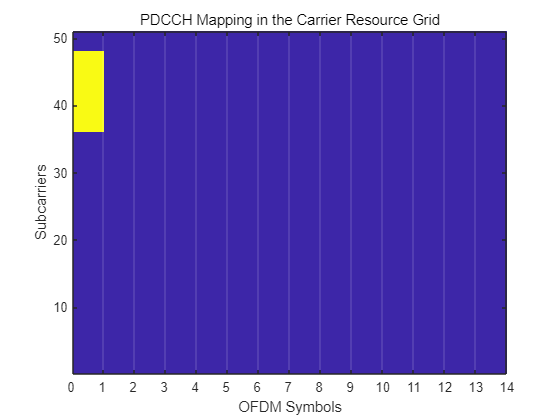

figure;
imagesc(abs(carrierGrid));
set(gca, 'XLim', [0.5, 14.5]);
set(gca, 'XTick', (0:14)+0.5);
set(gca, 'XTickLabel', (0:14));
set(gca, 'XGrid', 'on');
set(gca, 'GridColor', 'white');
set(gca, 'YDir', 'normal');
set(gca, 'YTick', (0:10:51)*12);
set(gca, 'YTickLabel', (0:10:51));
xlabel('OFDM Symbols');
ylabel('Subcarriers');
title('PDCCH Mapping in the Carrier Resource Grid');

function resource_map = getCoresetResourceMap(pdcch)
%   This function generates a resource map for the CORESET configuration
%   specified by the input parameter pdcch.

    crstCfg = pdcch.CORESET;

    % CORESET关键配置参数
    N_CORESET_REG = double(crstCfg.Duration)*sum(crstCfg.FrequencyResources)*6;
    CCE_total = double(crstCfg.Duration)*sum(crstCfg.FrequencyResources);
    if strcmp(crstCfg.CCEREGMapping,'interleaved')
        L = crstCfg.REGBundleSize;
        R = crstCfg.InterleaverSize;
        n_shift = crstCfg.ShiftIndex;
    else
        L = 6;
        R = 1;
        n_shift = 0;
    end
    C = N_CORESET_REG/(L*R);

    % PRB位图
    prb_map = nr5g.internal.pdcch.getCORESETPRB(crstCfg,pdcch.NStartBWP);

    % REG位图
    reg_map = reshape((1:N_CORESET_REG)-1,[crstCfg.Duration,sum(crstCfg.FrequencyResources)*6])';   % reshape函数按列排序，然后转置
    
    % REG bundle位图
    reg_bundle_map = floor(reg_map./L);
    
    % CCE和REG bundle的映射（交织器）
    reg_bundle_quene = (1:N_CORESET_REG/L)-1;
    reg_bundle_quene = circshift(reg_bundle_quene,-n_shift);
    interleaver_reg_bundle = reshape(reg_bundle_quene,[C,R])';  % 行进reg bundle
    interleaver_cce = reshape(interleaver_reg_bundle,6/L,[])';  % 列出CCE
    
    % CCE位图
    cce_map = ones(size(reg_bundle_map))*-1;
    for cceInd = 1:CCE_total
        reg_bundle_set = interleaver_cce(cceInd,:);
        reg_bundle_map_index = false(size(reg_bundle_map));

        % Find the indices in reg_bundle_map that match the current reg_bundle_set
        for idx = 1:length(reg_bundle_set)
            tmp = reg_bundle_map == reg_bundle_set(idx);
            reg_bundle_map_index = tmp| reg_bundle_map_index;
        end

        % Assign the CCE index to the matching entries in cce_map
        cce_map(reg_bundle_map_index) = cceInd - 1;
    end
    
    % PRB位图、REG位图、REG bundle位图和CCE位图合并
    table_header = {'prb_map', 'reg_map', 'reg_bundle_map','cce_map'};
    resource_map = table(flipud(prb_map),flipud(reg_map),flipud(reg_bundle_map),flipud(cce_map), 'VariableNames', table_header);

end

function candidates = getAllCCEIndexes(carrier, pdcch)
% This function calculates the candidate CCE (Control Channel Element) indexes for a given carrier and PDCCH (Physical Downlink Control Channel) configuration.
    
    % Extract relevant configurations from input parameters
    ssCfg = pdcch.SearchSpace;
    crstCfg = pdcch.CORESET;
    rnti = pdcch.RNTI;
    nCI = 0; % Assumes nCI = 0 (carrier indicator field)

    numCCEs = double(crstCfg.Duration) * sum(crstCfg.FrequencyResources);

    % Check if the current slot is an occasion for PDCCH transmission
    [isOccasion, slotNum] = nr5g.internal.pdcch.isOccasion(carrier, pdcch);
    
    % Get the value of Yp for the given search space type, CORESET ID, RNTI, and slot number
    Yp = nr5g.internal.pdcch.getYp(ssCfg.SearchSpaceType, ssCfg.CORESETID, rnti, slotNum);

    % Determine candidates for aggregation level
    if isOccasion
        MsAL = ssCfg.NumCandidates(log2(pdcch.AggregationLevel) + 1);
        L = pdcch.AggregationLevel;
        cceStartIdx = zeros(1, MsAL, 'uint32');
        for ms = 0:MsAL-1
            cceStartIdx(ms+1) = L * (mod(Yp + floor(double(ms*numCCEs)/double(L*MsAL)) + nCI, floor(numCCEs/L)));
        end
        candidates = cceStartIdx;
    else
        candidates = [];
    end
end